#     [IPSA] - Automatique - Projet drone

# Fichier de paramètres

Auteur : Adrien Jacob 

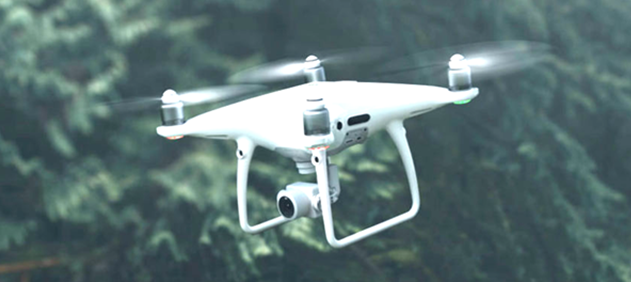   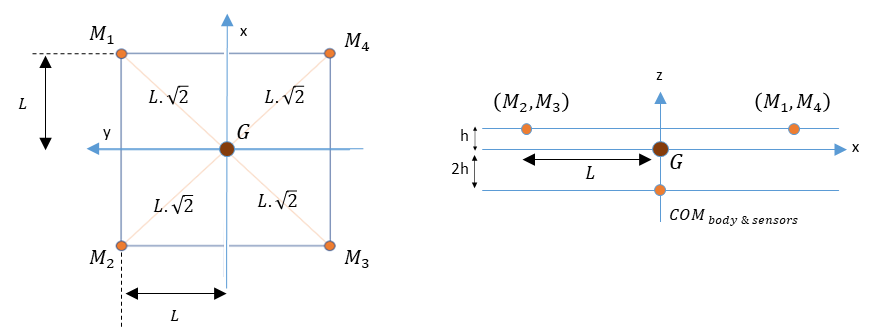

## **Definition du cahier des charges**

*cf. Partie 02*

**...**

## **Paramètres du drone**

______________________________________________________________________________________________________________

**1. Environnement : **

g = 9.81;           % [m/s²] gravity

______________________________________________________________________________________________________________

**2. Géométrie :**

m = 1.38;            % [kg] total weight 
L = 0.175;           % [m] 
h = 0.05/3;           % [m]
z_ground = 0.15;   % [m] drone COM altitude above ground
angle_max= 0.3491;




vx_ref = 20;
vy_ref = 20;
vz_ref = 5;
vpsi_ref = pi;


%% prefiltrage consigne (cf. 2.)
v_ref = [vx_ref , vy_ref , vz_ref , vpsi_ref];


______________________________________________________________________________________________________________

**3. Moteurs : **          

conv_rpm2rad = (2*pi)/60; % pour les conversions

% Documentation constructeur (à modifier)
Moteur_T_max = 34;           % [N] poussée max 
Moteur_T_hover = (m*g)/4;         % [N] poussée en hover d'un moteur
Moteur_T_dispo = (Moteur_T_max / 4) - Moteur_T_hover;;      % [N] poussée disponible d'un moteur au dessus du hover
Moteur_RPM_max = 10500;         % [RPM] vitesse max de rotation des hélices
Moteur_RPM_min = 0;         % [RPM] vitesse min de rotation des hélices

% Evaluation de kt, kc, km (à modifier, voir document d'introduction)

W_max = Moteur_RPM_max * conv_rpm2rad; % [rad/s] Vitesse max

kt = (Moteur_T_max/4) / (W_max^2);                % [N/(rad/s)²] coefficient de poussée
kc = 0.2*kt;                                      % [N.m/(rad/s)²] coefficient de contre-couple
km = kc/kt;                                  % [m]

% Calcul vitesses hélices w^2 (à modifier)
Wmot2_hover = Moteur_T_hover / kt;          % [(rad/s)²]
Wmot2_sat_min = (Moteur_RPM_min * conv_rpm2rad)^2;    % [(rad/s)²]
Wmot2_sat_max = (W_max)^2;        % [(rad/s)²]

Wmot2_sat = [Wmot2_sat_min , Wmot2_sat_max]; 

% Matrice de motor mixing (voir document d'introduction)
M = [1 1 1 1;-L L L -L;-L -L L L;-km km -km km];



______________________________________________________________________________________________________________

**4. Moment d'inertie : **`Ix, Iy, Iz [kg*m^2]`

% position des masses [m] 
X0=[0,0,-2*h]; X1=[ L,L,h]; X2=[ -L,L,h]; X3=[-L,-L,h]; X4=[L,-L,h];

% répartition des masses [kg] 
dm0=m/2; dm1=m/8; dm2=m/8; dm3=m/8; dm4=m/8; 

% calculs des produits d'inertie
Ixy = X0(1)*X0(2)*dm0 + X1(1)*X1(2)*dm1 + X2(1)*X2(2)*dm2 + X3(1)*X3(2)*dm3 + X4(1)*X4(2)*dm4; Iyx = Ixy;
Iyz = X0(3)*X0(2)*dm0 + X1(3)*X1(2)*dm1 + X2(3)*X2(2)*dm2 + X3(3)*X3(2)*dm3 + X4(3)*X4(2)*dm4; Izy = Iyz;
Ixz = X0(1)*X0(3)*dm0 + X1(1)*X1(3)*dm1 + X2(1)*X2(3)*dm2 + X3(1)*X3(3)*dm3 + X4(1)*X4(3)*dm4; Izx = Ixz;

% calculs des moments d'inertie
Ix2=X0(1)*X0(1)*dm0 + X1(1)*X1(1)*dm1 + X2(1)*X2(1)*dm2 + X3(1)*X3(1)*dm3 + X4(1)*X4(1)*dm4;
Iy2=X0(2)*X0(2)*dm0 + X1(2)*X1(2)*dm1 + X2(2)*X2(2)*dm2 + X3(2)*X3(2)*dm3 + X4(2)*X4(2)*dm4;
Iz2=X0(3)*X0(3)*dm0 + X1(3)*X1(3)*dm1 + X2(3)*X2(3)*dm2 + X3(3)*X3(3)*dm3 + X4(3)*X4(3)*dm4;
Ix=Iy2+Iz2; Iy=Ix2+Iz2; Iz=Ix2+Iy2;

% définition de la matrice d'inertie (dans RB)
I = [Ix   -Ixy   -Ixz
    -Iyx   Iy    -Iyz
    -Izx  -Izy    Iz];

______________________________________________________________________________________________________________

**5. Coefficients de trainé linéaire : **$k_{\textrm{vx}} ,k_{\textrm{vy}} ,k_{\textrm{vz}}$` [N*s/m]`

kvx = 0.1;
kvy = 0.1;
kvz = 0.3;

______________________________________________________________________________________________________________

**6. Coefficients de trainée rotationnelle : **$k_p ,k_q ,k_r$` [N*s/m/rad]`

kp = 0.01;
kq = 0.01;
kr = 0.005;

______________________________________________________________________________________________________________

**7. Structure params utile et affichage**

% structure de paramètres utiles :
params = struct(...
    'g', g, ...                     % [m/s²] gravité
    'm', m, ...                     % [kg] masse totale
    'L', L, ...                     % [m] longueur bras
    'h', h, ...                     % [m] hauteur
    'z_ground', z_ground, ...       % [m] altitude COM au-dessus du sol
    'Moteur_T_max', Moteur_T_max, ...
    'Moteur_T_hover', Moteur_T_hover, ...
    'Moteur_T_dispo', Moteur_T_dispo, ...
    'Moteur_RPM_max', Moteur_RPM_max, ...
    'Moteur_RPM_min', Moteur_RPM_min, ...
    'angle_max',angle_max, ...
    'v_ref', v_ref, ...
    'kt', kt, ...                   % [N/(rad/s)²] coefficient de poussée
    'kc', kc, ...                   % [N.m/(rad/s)²] coefficient de contre-couple
    'km', km, ...                   % [m] rapport kc/kt
    'Wmot2_hover', Wmot2_hover, ... % [(rad/s)] vitesses min/max moteur
    'Wmot2_sat', Wmot2_sat, ...     % [(rad/s)²] vitesses² min/max moteur
    'M' , M, ...                    % Matrice de "motor mixing"
    'I', I, ...                     % [kg.m²] matrice d'inertie 3x3
    'Ix', Ix, ...                   % [kg.m²] moment d'inertie en x
    'Iy', Iy, ...                   % [kg.m²] moment d'inertie en y
    'Iz', Iz, ...                   % [kg.m²] moment d'inertie en z
    'kvx', kvx, ...                 % [N.s/m] traînée linéaire x
    'kvy', kvy, ...                 % [N.s/m] traînée linéaire y
    'kvz', kvz, ...                 % [N.s/m] traînée linéaire z
    'kp', kp, ...                   % [N.m.s/rad] traînée rotationnelle p
    'kq', kq, ...                   % [N.m.s/rad] traînée rotationnelle q
    'kr', kr ...                    % [N.m.s/rad] traînée rotationnelle r
);

% nettoyage du workspace :
clear g m L h z_ground RPM ...
      kt kc km Wmot2_hover Wmot2_sat_min Wmot2_sat_max Wmot2_sat M ...
      Moteur_T_max Moteur_T_hover Moteur_T_dispo Moteur_RPM_max Moteur_RPM_min angle_max v_ref...
      X0 X1 X2 X3 X4 dm0 dm1 dm2 dm3 dm4 I Ix Iy Iz Ixy Iyz Ixz Iyx Izx Izy Ix2 Iy2 Iz2 ...
      kvx kvy kvz kp kq kr;

% Affichage
disp('=== Paramètres du drone ===');

=== Paramètres du drone ===


disp(' '); disp(params);

 
                 g: 9.8100
                 m: 1.3800
                 L: 0.1750
                 h: 0.0167
          z_ground: 0.1500
      Moteur_T_max: 34
    Moteur_T_hover: 3.3844
    Moteur_T_dispo: 5.1156
    Moteur_RPM_max: 10500
    Moteur_RPM_min: 0
         angle_max: 0.3491
             v_ref: [20 20 5 3.1416]
                kt: 7.0304e-06
                kc: 1.4061e-06
                km: 0.2000
       Wmot2_hover: 4.8140e+05
         Wmot2_sat: [0 1.2090e+06]
                 M: [4×4 double]
                 I: [3×3 double]
                Ix: 0.0221
                Iy: 0.0221
                Iz: 0.0423
               kvx: 0.1000
               kvy: 0.1000
               kvz: 0.3000
                kp: 0.0100
                kq: 0.0100
                kr: 0.0050

